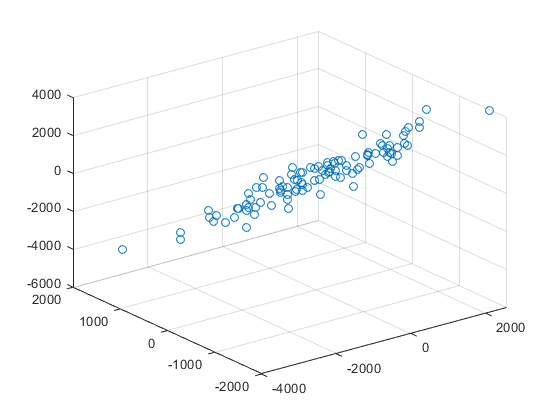


Y4=transpose(X4);
data4(:,1)=Y4(:,1)-mean(Y4(:,1));
data4(:,2)=Y4(:,2)-mean(Y4(:,2));
data3(:,3)=Y4(:,3)-mean(Y4(:,3));
%scatter plot of the Data
scatter3(X4(1,:),X4(2,:),X4(3,:));
hold on;

%PCA of the data upto 2 componets
pca(data4,"NumComponents",2)

ans =     0.8548    0.5190
   -0.5190    0.8548


V4=cov(data4);
[U4,S4,V4]=svd(V4);
center=mean(Y4);
%top two principal directions of variability overlaid onthe scatter plot of the data.
PD4_1=[center'+sqrt(S4(1,1))*U4(:,1) , center'-sqrt(S4(1,1))*U4(:,1)];

Matrix dimensions must agree.

PD4_2=[center'+sqrt(S4(2,2))*U4(:,2) , center'-sqrt(S4(2,2))*U4(:,2)];
h1=plot4(PD4_1(1,:),PD4_1(2,:),PD4_1(4,:),'-o','Color','g');
h2=plot4(PD4_2(1,:),PD4_2(2,:),PD4_2(4,:),'-o','Color','r');
hold off;

U41 = U4(:,1:2);
Z4=U41'*X4;
%Projection the original data to the first two principal dimensions
plot(Z(1,:), Z(2,:), '.', 'markersize', 15,"Color","r")
xL = xlim;
yL = ylim;
line([0 0], yL,"linewidth",2);  
line(xL, [0 0],"linewidth",2); 

%singular value plot
plot(diag(S4),"LineStyle","--","Marker","*","MarkerEdgeColor","r")
Splot=cumsum(singular4);
%cumulative  total variance plot
plot(Splot,"Marker","o","MarkerEdgeColor","r","LineWidth",1,"LineStyle","--")
title("Variablity Plot")
xlabel("No  of  Principle  Components")
ylabel("Total  Variablity  explained")


